clear all, close all, clc;

# Data Derivative using Fast Fourier Transform


$$\text{simple approach}:
f_k^\prime \approx \frac{f_{k+1} - f_k}{\Delta x}$$



$$\text{using fft}:
\mathcal{F} \Big( \frac{df}{dx} \Big) = i \pmatrix {\vdots \cr \kappa \cr \vdots}
\pmatrix {\vdots \cr \hat{f} \cr \vdots}$$



$$\kappa - \text{spatial frequency} \\
\omega - \text{temporal frequency}$$


n = 64;
L = 30;
dx = L/n;
x = -L/2:dx:L/2;
f = cos(x).*exp(-x.^2/25);                      % Function
df = -( sin(x).*exp(-x.^2/25) + (2/25)*x.*f );  % Derivative

**Approximate Derivative using finite Difference**

for kappa = 1:length(f)-1
    dfFD(kappa) = ( f(kappa + 1) - f(kappa) )/dx;
end
dfFD(end+1) = dfFD(end);

**Derivative using FFT (spectral derivative)**

fhat = fft(f);
kappa = (2*pi/L)*[-n/2:n/2];
kappa = fftshift(kappa);
dfhat = i*kappa.*fhat;
dfFFT = real(ifft(dfhat));

**Plotting**

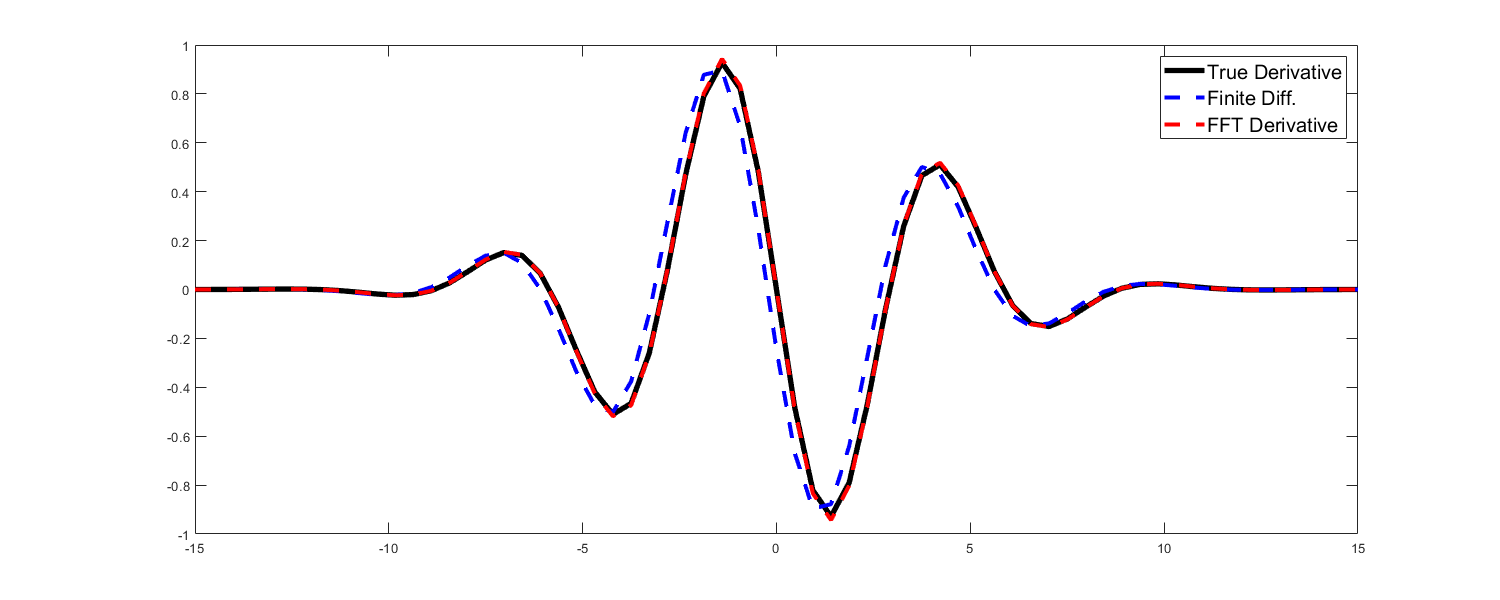

figure('Position',[0 0 1500 600])
plot(x, df, 'k', 'LineWidth', 4, "DisplayName",'True Derivative'), hold on
plot(x, dfFD, 'b--', "LineWidth", 3, "DisplayName", 'Finite Diff.')
plot(x, dfFFT, 'r--', "LineWidth", 3, "DisplayName", 'FFT Derivative')
legend("FontSize", 15)